EE3510 HW2 105060012張育菘

1. Simulate spring-mass-damper system of unforced response with damping ratio equal to 0.3, 0.6, and 1 (see Fig. 2.46) (p.108)

Ans. 


$$\begin{array}{l}
\ddot{y} +\frac{b}{M}\dot{y} +\frac{k}{M}y=-\frac{r\left(t\right)}{M_s }\\
\mathrm{Condition}:\frac{b}{M}=2\xi \omega_n ,\frac{k}{M}=\omega_n^2 ,=2\dot{y} \left(0\right)=2,y\left(0\right)=-1\\
\Longrightarrow \left(s^2 Y\left(s\right)-\mathrm{sy}\left(0\right)-\dot{y} \left(0\right)\right)+\frac{b}{M}\left(\mathrm{sY}\left(s\right)-y\left(0\right)\right)+\frac{k}{M}Y\left(s\right)=-\frac{P}{s}
\end{array}$$



$$\Longrightarrow Y\left(s\right)=\frac{-s^2 +\left(2-\frac{b}{M}\right)s-P}{s\left(s^2 +\frac{b}{M}s+\frac{k}{M}\right)}$$


close all; clear;

% Damping ratio is (b/M)/(2wn), wn = sprt(k/M) = sqrt(2)
% the magnitude of the step response is P

fprintf('Using Inverse Laplace Transform to get the output signal in time domain\n');

Using Inverse Laplace Transform to get the output signal in time domain


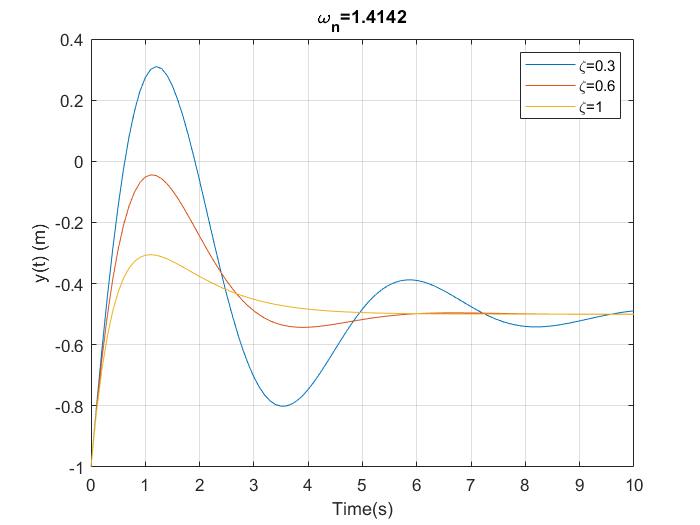

wn = sqrt(2); 
zeta = [0.3 0.6 1]; 

% function [y_t] = ilap(P,damp_ratio,wn)
y_t1 = ilap(1,0.3,sqrt(2));
y_t2 = ilap(1,0.6,sqrt(2));
y_t3 = ilap(1,1,sqrt(2));

t = [0:0.1:10];
figure; 
plot(t, y_t1(t), t, y_t2(t), t, y_t3(t)); grid;
xlabel('Time(s)'), ylabel('y(t) (m)');
title(['\omega_n=',num2str(wn)]);
legend(['\zeta=',num2str(zeta(1))],['\zeta=',num2str(zeta(2))],['\zeta=',num2str(zeta(3))]);


$$\Longrightarrow y\left(t\right)=\frac{y\left(0\right)}{\sqrt{1-\zeta^2 }}e^{-\zeta \omega_n t} \mathrm{sin}\left(\omega_n \sqrt{1-\zeta^2 }t+\theta \right),\theta ={\mathrm{cos}}^{-1} \zeta$$


fprintf('by equation of output signal in time domain\n');

by equation of output signal in time domain


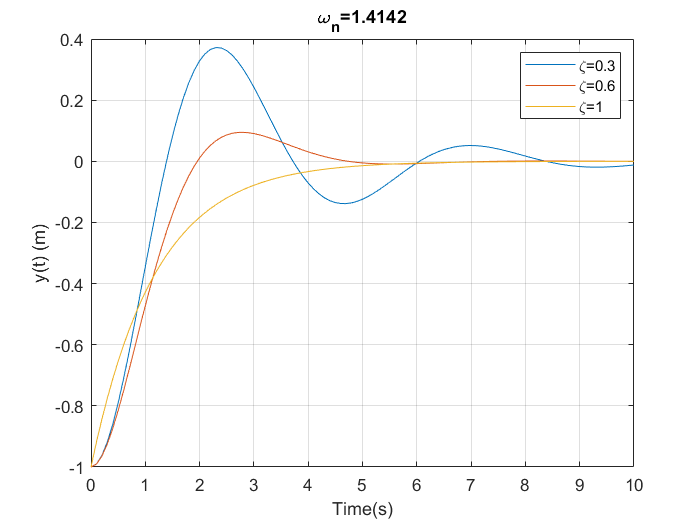

y0 = -1; 
wn = sqrt(2); 
zeta = [0.3 0.6 1]; 
t = [0:0.1:10];
y = zeros(3,length(t));

%Compute Unforced Response to an Initial Condition 
for i=1:1:length(zeta)-1
    c = (y0/sqrt(1-zeta(i)^2)); 
    for j=1:1:length(t)
        y(i, j) = c*exp(-zeta(i)*wn*t(j)).*sin(wn*sqrt(1-zeta(i)^2)*t(j)+acos(zeta(i)));
    end
end

for j=1:1:length(t)
    y(length(zeta), j) = c*exp(-zeta(i)*wn*t(j)).*sin(wn*0*t(j)+acos(zeta(i)));
end

figure; plot(t,y); grid;
xlabel('Time(s)'), ylabel('y(t) (m)');
title(['\omega_n=',num2str(wn)]);
legend(['\zeta=',num2str(zeta(1))],['\zeta=',num2str(zeta(2))],['\zeta=',num2str(zeta(3))]);

2. Simulate Example 2.19 (Series connection) (p.120)


$$G\left(s\right)=\frac{1}{500s^2 },G_c \left(s\right)=\frac{s+1}{s+2}$$



$$\mathrm{sys1}=G_c \left(s\right)G\left(s\right)$$



$$\mathrm{sys2}=\frac{G_c \left(s\right)G\left(s\right)}{1+G_c \left(s\right)G\left(s\right)}$$


close all; clear;
numg = [1]; deng = [500 0 0]; sysg = tf(numg,deng);
numgc = [1 1]; dengc = [1 2]; sysgc = tf(numgc,dengc); 
sys1 = series(sysg,sysgc)


sys1 =
 
        s + 1
  ------------------
  500 s^3 + 1000 s^2
 
Continuous-time transfer function.




sys2_num = series(sysg,sysgc); 
sys2 = feedback(sys2_num,[1])


sys2 =
 
            s + 1
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.



3. Simulate Example 2.20 (The feedback function with unity feedback) (p.123)


$$G\left(s\right)=\frac{1}{500s^2 },G_c \left(s\right)=\frac{s+1}{s+2}$$



$$T_1 \left(s\right)=\frac{G_c \left(s\right)G\left(s\right)}{1+G_c \left(s\right)G\left(s\right)},T_2 \left(s\right)=\frac{G\left(s\right)}{1\mp G_c \left(s\right)G\left(s\right)}$$



$$T_{2-1} \left(s\right)=\frac{G\left(s\right)}{1+G_c \left(s\right)G\left(s\right)},T_{2-2} \left(s\right)=\frac{G\left(s\right)}{1-G_c \left(s\right)G\left(s\right)}$$


close all; clear;
numg = [1]; deng = [500 0 0]; sysg = tf(numg,deng);
numgc = [1 1]; dengc = [1 2]; sysgc = tf(numgc,dengc);  
T1_num = series(sysg,sysgc); 
T1 = feedback(T1_num,[1],-1)


T1 =
 
            s + 1
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.




T2_1 = feedback(sysg,sysgc,-1)


T2_1 =
 
            s + 2
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.



T2_2 = feedback(sysg,sysgc,+1)


T2_2 =
 
            s + 2
  --------------------------
  500 s^3 + 1000 s^2 - s - 1
 
Continuous-time transfer function.

